% Supplementary Analysis 5 - Cross-validation model comparisons using regression rather than classification models - SM outcome

clc;
clear all;
close all;

% Add path to functions
addpath(genpath('/Shared/boeslab/Users/jcgriffis/vips_psom_prediction/final_archive_scripts/'));

% Analysis inputs
model_spec = 'ridge';
modalities = {'base', 'expanded_pos' 'expanded_vips_pos'}; % use only positive model weights to generate pediatric predictions
beh_col = 'contra_motor'

beh_col = 'contra_motor'

min_stroke_age = 0;
min_test_age = 0;
min_test_interval = 0.5;
min_freq = 1;
min_freq_stack = 1;
pos_only = 1;

% Path to adult SM model
sm_col = "gpb_dif";
sm_dir = '/Shared/boeslab/Users/jcgriffis/vips_psom_prediction/registry_models/motor';    
sm_model_dir = 'plsr_all_lesion_d0_all_flip_ui';
sm_model_path = fullfile(sm_dir, sm_col, sm_model_dir);

% Fit base and expanded models
for i = 1:length(modalities)
    cv_models{i,1} = run_vips_psom_models_cv2(sm_model_path, modalities{i}, model_spec, beh_col, min_stroke_age, min_test_age, min_test_interval,...
        min_freq, min_freq_stack, 0, pos_only);   
    load(fullfile(cv_models{i,1}, 'cv_results.mat'));
    results.(modalities{i}) = cv_results;
    clear cv_results
end

cfg.jackknife field is empty; setting to 0 with default settings
Analysis type is other - setting defaults for non-lesion analysis
MATLAB parallel processing functionality detected; parallel processing enabled
Trimming data to retain columns with at least 1 observations greater than or equal to 1
Preallocating CV results
Outer CV repeats:1/5
Running 5 repeats of 5-fold optimization for model hyperparameters
Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 40 workers.
Hyper-parameter optimization iteration:4/5
Hyper-parameter optimization iteration:5/5
Hyper-parameter optimization iteration:3/5
Hyper-parameter optimization iteration:1/5
Hyper-parameter optimization iteration:2/5
Optimal lambda = 0.0021083, fitting model with optimal lambda
Running 5 repeats of 5-fold optimization for model hyperparameters
Hyper-parameter optimization iteration:4/5
Hyper-parameter optimization iteration:5/5
Hyper-parameter optimization iteration:3/5
Hyper

% Plot results (Pearson)
clf;

% Gather test fold correlations
plot_results = zeros(25,3);
for j = 1:length(modalities)
    if j == 1
        group = ones(25,1);
    else
        group = [group;ones(25,1).*j];
    end
    plot_results(:,j)=results.(modalities{j}).corr(:);
end

% Plot results
b = boxchart(plot_results(:), 'GroupByColor', group, 'Notch', 'off');
if strcmp(beh_col, 'contra_motor')
    b(2).BoxFaceColor = b(1).BoxFaceColor;
    b(2).MarkerColor = b(1).MarkerColor;
else
    b(2).BoxFaceColor = [0.85, 0.325, 0.098];
    b(2).MarkerColor = [0.85, 0.325, 0.098];
end
b(1).BoxFaceColor = [0,0,0];
b(1).MarkerColor = [0,0,0];
l.IconColumnWidth = 10

l = struct with fields:
    IconColumnWidth: 10


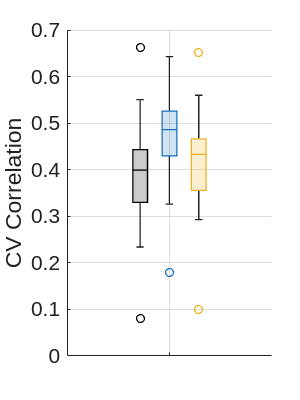

l.Box = "off";
axis('auto')
ylabel('CV Correlation'); grid on; set(gca, 'XtickLabelRotation', 45);
title(''); set(gca, 'FontSize', 16); set(gcf, 'position', [0, 0, 300, 400]); box off; set(gca, 'XtickLabel', '');

% Convert to Fisher z and compare correlations
plot_results = atan(plot_results);
[h, p, ci, stats] = ttest(plot_results(:,1), plot_results(:,2)) % base vs. expanded adult

h = 1

p = 2.3510e-09

ci =    -0.0857
   -0.0544


stats = struct with fields:
    tstat: -9.2183
       df: 24
       sd: 0.0380


[h, p, ci, stats] = ttest(plot_results(:,1), plot_results(:,3)) % base vs. expanded pediatric

h = 1

p = 1.9794e-05

ci =    -0.0292
   -0.0128


stats = struct with fields:
    tstat: -5.2936
       df: 24
       sd: 0.0198


[h, p, ci, stats] = ttest(plot_results(:,3), plot_results(:,2)) % expanded adult vs. expanded pediatric

h = 1

p = 3.0354e-08

ci =    -0.0617
   -0.0364


stats = struct with fields:
    tstat: -8.0176
       df: 24
       sd: 0.0306


% Plot results (Spearman)
clf; clear plot_results

% Get CV test fold rank correlations
cv_rho = zeros(5,5);
for j = 1:length(modalities)
    if j == 1
        group = ones(25,1);
    else
        group = [group;ones(25,1).*j];
    end
    for i = 1:5
        for k = 1:5
            cv_rho(i,k) = corr(results.(modalities{j}).pred_y(:,i,k), results.(modalities{j}).obs_y(:,i,k), 'rows', 'pairwise', 'type', 'Spearman');
        end
    end
    plot_results(:,j) = cv_rho(:);
    clear cv_rho
end

% Plot results
b = boxchart(plot_results(:), 'GroupByColor', group, 'Notch', 'off');
if strcmp(beh_col, 'contra_motor')
    b(2).BoxFaceColor = b(1).BoxFaceColor;
    b(2).MarkerColor = b(1).MarkerColor;
else
    b(2).BoxFaceColor = [0.85, 0.325, 0.098];
    b(2).MarkerColor = [0.85, 0.325, 0.098];
end
b(1).BoxFaceColor = [0,0,0];
b(1).MarkerColor = [0,0,0];
l.IconColumnWidth = 10

l = struct with fields:
    IconColumnWidth: 10
                Box: "off"


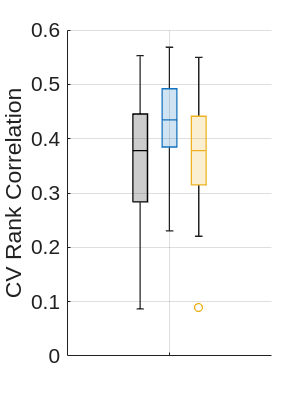

l.Box = "off";
axis('auto')
ylabel('CV Rank Correlation'); grid on; set(gca, 'XtickLabelRotation', 45);
title(''); set(gca, 'FontSize', 16); set(gcf, 'position', [0, 0, 300, 400]); box off; set(gca, 'XtickLabel', '');

plot_results = atan(plot_results);
[h, p, ci, stats] = ttest(plot_results(:,1), plot_results(:,2)) % base vs. expanded adult

h = 1

p = 4.5741e-05

ci =    -0.0860
   -0.0355


stats = struct with fields:
    tstat: -4.9623
       df: 24
       sd: 0.0612


[h, p, ci, stats] = ttest(plot_results(:,1), plot_results(:,3)) % base vs. expanded pediatric

h = 1

p = 0.0092

ci =    -0.0233
   -0.0037


stats = struct with fields:
    tstat: -2.8318
       df: 24
       sd: 0.0238


[h, p, ci, stats] = ttest(plot_results(:,3), plot_results(:,2)) % expanded adult vs. expanded pediatric

h = 1

p = 8.6352e-05

ci =    -0.0679
   -0.0265


stats = struct with fields:
    tstat: -4.7121
       df: 24
       sd: 0.0501
